# ECE 580 HW3

Yen-Chun Chen

934559635

### 1. Find the expressions in terms of the element values for the dc gain, the pole frequency (ωo) and the pole  Q (Qp), for the Delyiannis and Rauch filters.

**Delyiannis-Friend Filter:**

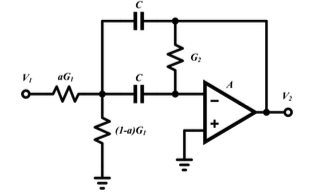

Transfer Function with an ideal op-amp:


$$H\left(s\right)\;=\;-\frac{{\textrm{saCG}}_1 }{s^2 C^2 +2{\textrm{sCG}}_2 +G_1 G_2 }\;=\;-\frac{\frac{{\textrm{saG}}_1 }{C}}{s^2 +s\frac{2G_2 }{C}+\frac{G_1 G_2 }{C^2 }}$$


The DC Gain: $\lim_{s\to 0} H\left(s\right)=\;H\left(0\right)\;=0$

The transfer function for a general second order low-pass filter is given

$H\left(s\right)=\frac{A_v \;{\omega_0 }^2 }{s^2 +\frac{\omega_0 }{Q}s+{\omega_0 }^2 }$ ,  we got that $\omega_0^2 \;=\;\frac{G_1 G_2 }{C^2 }$   Thus, the pole frequency $\omega_0 \;=\;\frac{\sqrt{G_1 G_2 }}{C}$

Pole Q is determined by the coefficient of *s* in the denominator

So we got  $\frac{\omega_0 }{Q_p }\;=\;\frac{2G_2 }{C }\;\to Q_p \;=\;\frac{\sqrt{G_1 G_2 }}{C}\;\frac{C}{2G_2 }\;=\;\frac{1}{2}\sqrt{\frac{G_1 }{G_2 }}\;$

**Rauch Filter:**

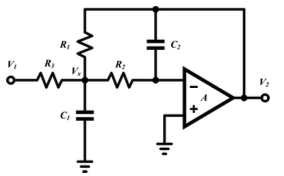

Transfer Function: $H\left(s\right)=\frac{\frac{G_2 G_3 }{C_1 C_2 }}{s^2 +s\left(\frac{G_1 {+G}_2 +G_3 }{C_1 }\right)+\frac{G_1 G_2 }{C_1 C_2 }+\varepsilon }$


$$\varepsilon =\frac{1}{A}\left\lbrack s^2 +s\left(\frac{G_1 +G_2 +G_3 }{C_1 }+\frac{G_2 }{C_2 }\right)+\frac{\left(G_1 +G_3 \right)G_2 }{C_1 C_2 }\right\rbrack$$


For an ideal op-amp, $A\to \infty$ leads to $\varepsilon \to 0$.  Thus, the DC Gain: $\lim_{s\to 0} H\left(s\right)=\;H\left(0\right)\;=\;\frac{\frac{G_2 G_3 }{C_1 C_2 }}{\frac{G_1 G_2 }{C_1 C_2 }}\;=\;\frac{G_3 }{G_1 }$

The transfer function for a general second order low-pass filter is given

$H\left(s\right)=\frac{A_v \;{\omega_0 }^2 }{s^2 +\frac{\omega_0 }{Q}s+{\omega_0 }^2 }$ ,  we got that $\omega_0^2 \;=\;\frac{G_1 G_2 }{C_1 C_2 }$   Thus, the pole frequency $\omega_0 \;=\;\sqrt{\frac{G_1 G_2 }{C_1 C_2 }}$

Pole Q is determined by the coefficient of *s* in the denominator

So we got  $\frac{\omega_0 }{Q_p }\;=\;\frac{G_1 {+G}_2 +G_3 }{C_1 }\;\to Q_p \;=\;\sqrt{\frac{G_1 G_2 }{C_1 C_2 }}\left(\frac{C_1 }{G_1 +G_2 +G_3 }\right)$

###  2. Design a Rauch filter for the following specifications:

###  $R_1 =1\;\textrm{kΩ}$, $R_2 =0\ldotp 5\;\textrm{kΩ}$, $\textrm{DC}\;\textrm{gain}=1$, $Q_p =2^{-\frac{1}{2}}$, $\omega_0 =40\pi \;\textrm{krad}/s$

#### Please output the performance characteristics of the filter (gain/frequency response/zero pole, etc.)

clear
close all
clc

R1 = 1e3;        % 1k ohms
R2 = 500;        % 500 ohms
DC_gain = 1;     % DC Gain
Q_p = 2^(-0.5);  % Quality factor
w_0 = 2*pi*20e3; % Pole Frequency (rad/s)

G1 = 1/R1;
G2 = 1/R2;
G3 = G1*DC_gain; % H(0) = G3/G1

% Calculate C1 and C2
C1C2 = G1 * G2 / w_0^2;
C1 = Q_p * (G1 + G2 + G3) / w_0;
C2 = C1C2 / C1;
fprintf('G1 = %.d mho\nG2 = %.d mho\nG3 = %.d mho\nC1 = %.6e F\nC2 = %.6e F\nDC Gain = %.2f\nQ_p = %.4f\nw_0 = %.2f rad/s', G1, G2, G3, C1, C2, DC_gain, Q_p, w_0);

G1 = 1e-03 mho
G2 = 2e-03 mho
G3 = 1e-03 mho
C1 = 2.250791e-08 F
C2 = 5.626977e-09 F
DC Gain = 1.00
Q_p = 0.7071
w_0 = 125663.71 rad/s

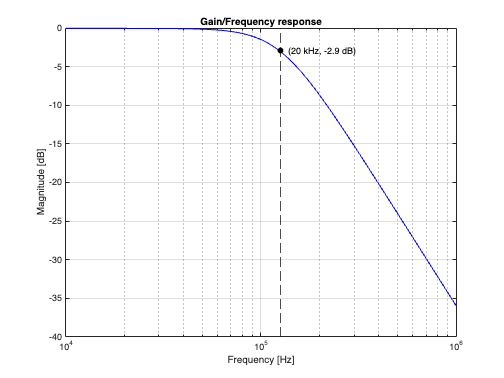

num = [0 , 0 , (G2 * G3)/(C1 * C2)];         % Numerator
den = [1 , (G1+G2+G3)/C1 , (G1*G2)/(C1*C2)]; % Denominator
tf_sys = tf(num, den);
[H, w] = freqs(num, den);

% Magnitude response
mag_dB = 20*log10(abs(H));
[~, idx] = min(abs(w - w_0)); % Find the magnitude at w_0
mag_at_w0 = mag_dB(idx);

figure(1);
semilogx(w, mag_dB, 'b');
% Plot the intersection point
hold on;
xline(w_0, 'k--', 'LineWidth', 1);
plot(w_0, mag_at_w0, 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'k');
text(w_0*1.1, mag_at_w0, sprintf('(%0.d kHz, %0.1f dB)', w_0/(2*pi)/1000, mag_at_w0));
hold off;
title("Gain/Frequency response");
ylabel("Magnitude [dB]");
xlabel("Frequency [Hz]");
grid on;

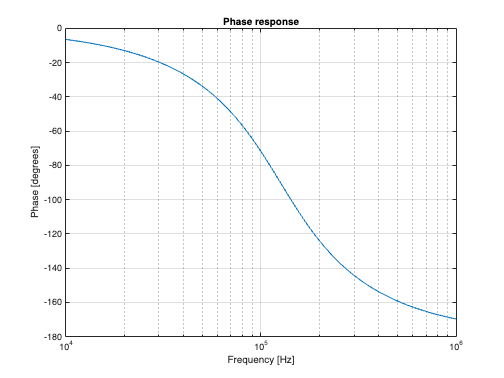

%Phase Response
figure(2);
semilogx(w, 180/pi*unwrap(angle(H))); % Plot phase in degrees
title("Phase response");
ylabel("Phase [degrees]");
xlabel("Frequency [Hz]");
grid on

% Poles and Zeros
[z, p, k] = tf2zp(num, den)

z =
  0×1 empty double column vector


p = 1.0e+04 *

  -8.8858 + 8.8858i
  -8.8858 - 8.8858i


k = 1.5791e+10

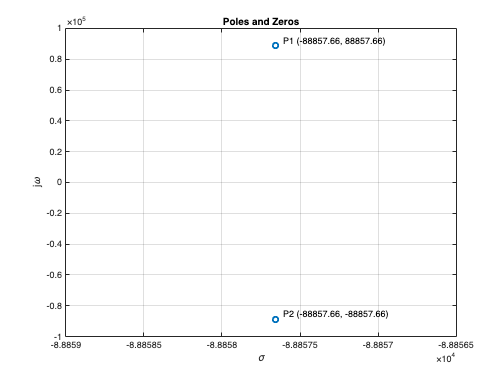

figure(3);
plot(z,'o');
plot(p,'o', 'LineWidth',2);
title("Poles and Zeros");
ylabel("j\omega");
xlabel("\sigma");
for i = 1:length(p)
    text(real(p(i)) + 0.05, imag(p(i)) + 0.05, ...
        sprintf('P%d (%.2f, %.2f)', i, real(p(i)), imag(p(i))), ...
        'HorizontalAlignment', 'left', 'VerticalAlignment', 'bottom');
end
grid on

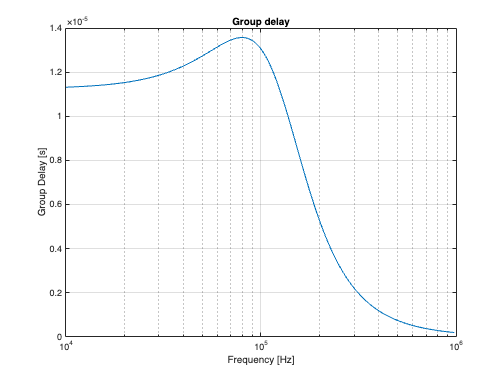

% Group delay
gd = -diff(unwrap(angle(H)))./diff(w);
figure(4);
semilogx(w(1:length(w)-1), gd);
ylabel("Group Delay [s]");
xlabel("Frequency [Hz]");
title("Group delay");
grid on

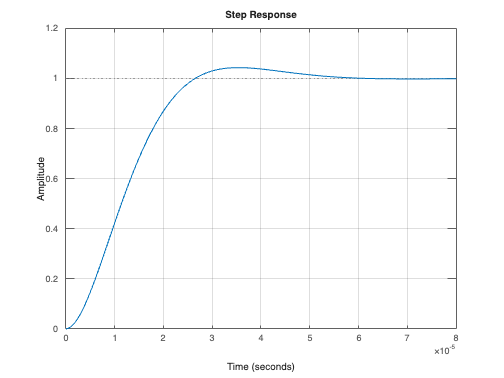

% Step Response
figure(5);
step(tf_sys);
title("Step Response");
grid on